# Arduino Step Response Experiment

#### Mini Project for SEED Lab

Alex Curtis

This script runs the step response experiment I created in stepResponse.ino, interperets the data, makes some beautiful plots, determines an accurate transfer function for the motor, and tunes a PI controller to desired specifications. 

*Upload the stepResponse code to the Arduino before running.*

#### Clear previous workspace data

clear dataTable dataArray

#### Automatically find the port the Arduino is connected to

allPorts = serialportlist;  % list of all available ports
pat = "/dev/cu.usbmodem";   % text to look for

% logical array of matching ports
matchingPorts = startsWith(allPorts, pat);   

if any(matchingPorts)                   % If any matches were found,              
    numMatches = sum(matchingPorts);    % Count the number of matches.
    if size(numMatches) > 1             % If multiple matching ports were found, 
        error("Multiple ports found")   % throw an error.
    else                                % If only one match was found,
        port = allPorts(matchingPorts); % that string is the arduino port.
    end
else                                    % If no ports were found,
    error("Port not found")             % throw an error.
end

#### Create a serialport object to talk to the Arduino

ard = serialport(port, 115200);   % creates a device object (port, baud)
configureTerminator(ard, "CR/LF") % sets the terminator

#### Wait for the Arduino

When the Arduino is ready, it sends "Ready!"

readline(ard);

#### Tell the Arduino to start the step experiment

disp('Starting Counting Event in Arduino')

Starting Counting Event in Arduino


writeline(ard,"S"); % sends the start command to the Arduino

Read data from Arduino

k = 0; % array index

% Read the first line of output from the Arduino
newData = readline(ard);

% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished',8)) 
    k = k + 1; % k++

    % save the line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end

clear ard; % Disconect from the Arduino

%cell2mat(stringArray)
% Transpose stringArray
%stringArray = stringArray';

% change string data to cell array using tab delimiter 
dataArray = str2double(stringArray);

% Make time start at 0 and convert from ms to s
dataArray(:,1) = (dataArray(:,1)-1000)/1000;

% Create a table to store the data
dataTable = array2table(dataArray,"VariableNames",{'time', 'motor', 'vel', 'pos'})

dataTable = 201×4 table
    time     motor     vel         pos   
    _____    _____    ______    _________

        0     255          0            0
    0.005     255     0.3927    0.0019635
     0.01     255     1.9635     0.011781
    0.015     255     3.5343     0.029452
     0.02     255     4.3197     0.051051
    0.025     255     4.7124     0.074613
     0.03     255     5.4978       0.1021
    0.036     255     6.2832      0.13352
     0.04     255     5.8905      0.16297
    0.045     255     7.4613      0.20028
     0.05     255     8.2467      0.24151
    0.055     255     8.6394      0.28471
     0.06     255     9.4248      0.33183
    0.065     255     9.8175      0.38092
     0.07     255      10.21      0.43197
    0.075     255      10.21      0.48302



% Save data to a .mat file
save stepData.mat dataTable

#### Plot the data (raw motor response)

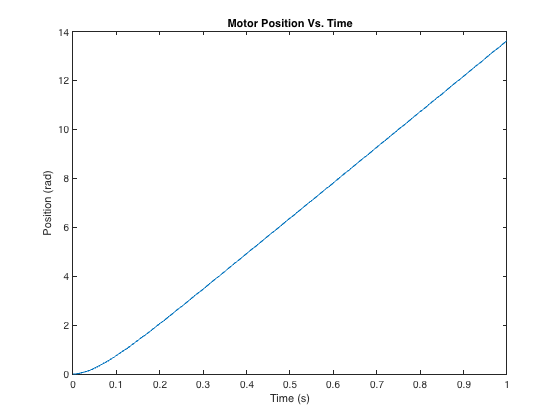

plot(dataTable.time,dataTable.pos)
title('Motor Position Vs. Time')
xlabel('Time (s)')
ylabel('Position (rad)')

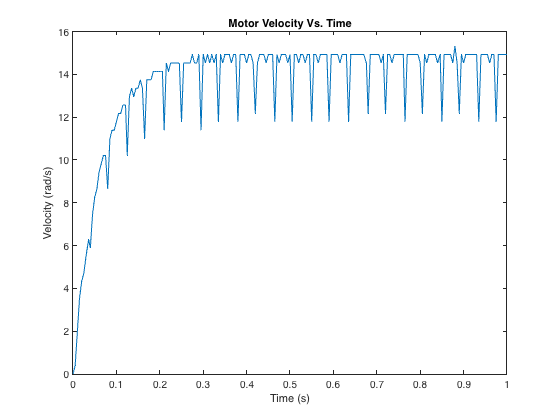


plot(dataTable.time,dataTable.vel)
title('Motor Velocity Vs. Time')
xlabel('Time (s)')
ylabel('Velocity (rad/s)')

#### Process data

Smoothing the velocity data gets rid of any noise that might mess up my resulting transfer function.

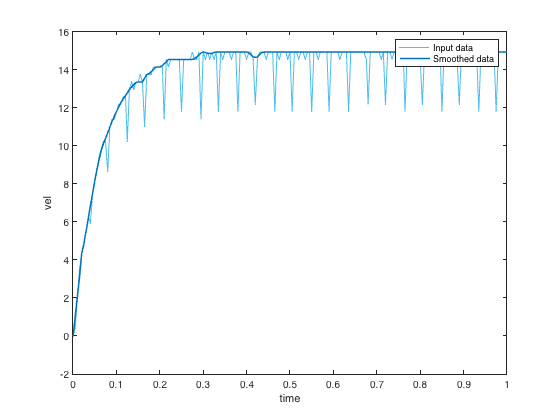

% Smooth input data
newT = smoothdata(dataTable,"rlowess","SmoothingFactor",0.2,...
    "DataVariables","vel","SamplePoints",dataTable.time);

% Display results
clf
plot(dataTable.time,dataTable.vel,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(dataTable.time,newT.vel,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
ylabel("vel")
xlabel("time")

Max analogWrite command = 255

max motor.setM1Speed() command = 400

Since the motor command is a number out of 400, I need to divide the velocity by 400 to get a unit step response.

**THIS HAS NOTHING TO DO WITH THE VOLTAGE ON THE BATTERY.**

newT.velScaled = newT.vel/400;

#### Plot the processed data (motor unit step response)

plot(newT.time,newT.velScaled)
xlabel('Time (s)')
ylabel('Velocity (rad/s)')
title('Motor Unit Step Response (Scaled Motor Velocity Vs. Time)')
hold on

#### Determine Transfer Function of Motor Command to Velocity

Find the steady state velocity of the motor (K)

K = newT.velScaled(newT.time > 0.4);
K = mean(K)

K = 0.0367

find 0.64 * K and the time constant to find sigma

magAtTimeConstant = max(newT.velScaled(newT.velScaled <= 0.64*K+0.1*K & newT.velScaled >= 0.64*K-0.1*K))

magAtTimeConstant = 0.0264

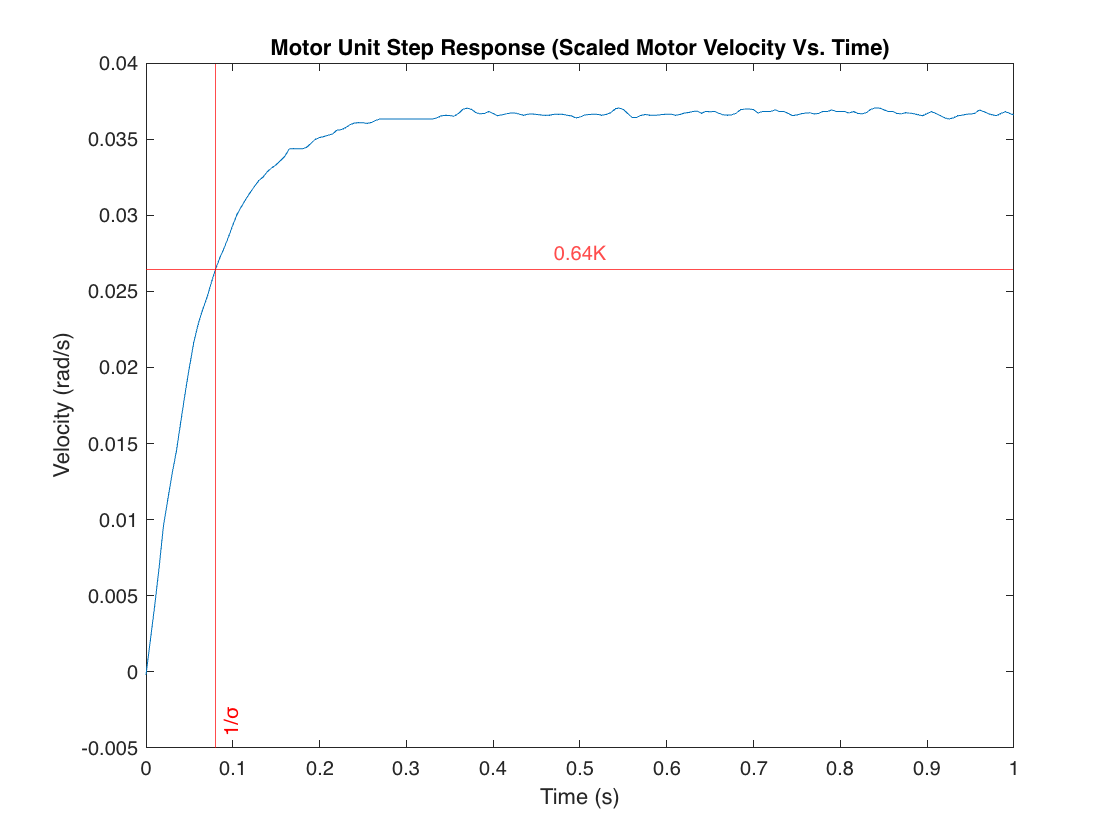

timeConstant = newT.time(newT.velScaled == max(magAtTimeConstant));

yline(magAtTimeConstant,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
xline(timeConstant,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')
hold off


sigma = 1./timeConstant;
sigma = mean(sigma)

sigma = 12.5000

With K and sigma, create the velocity and position transfer functions

s = tf('s');
velTF = K*(sigma)/(s+sigma)

velTF =
 
   0.4586
  --------
  s + 12.5
 
Continuous-time transfer function.



posTF = velTF*(1/s)

posTF =
 
     0.4586
  ------------
  s^2 + 12.5 s
 
Continuous-time transfer function.



Turn the generated transfer functions into coefficient arrays for use in Simulink.

posNum = posTF.Numerator;       % Find the numerator coefficients
posNum = posNum{1};             % Convert the numerator to a the right form
posDen = posTF.Denominator;     % Find the denominator coefficients
posDen = posDen{1};             % Convert the denominator to a the right form

velNum = velTF.Numerator;       % Find the numerator coefficients
velNum = velNum{1};             % Convert the numerator to a the right form
velDen = velTF.Denominator;     % Find the denominator coefficients
velDen = velDen{1};             % Convert the denominator to a the right form

#### Compare the Transfer Function with Motor Response

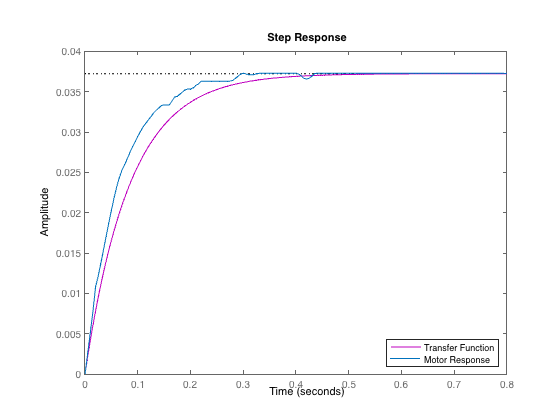

step(velTF,'m')
hold on
plot(newT.time,newT.velScaled)
legend('Transfer Function','Motor Response','Location','southeast')
hold off

#### Design a PI Controller to Regulate Position

Design a PI controller that achieves closed loop step response specifications of a rise time of 1 second and an overshoot of less than or equal to 12%, with zero steady state error.

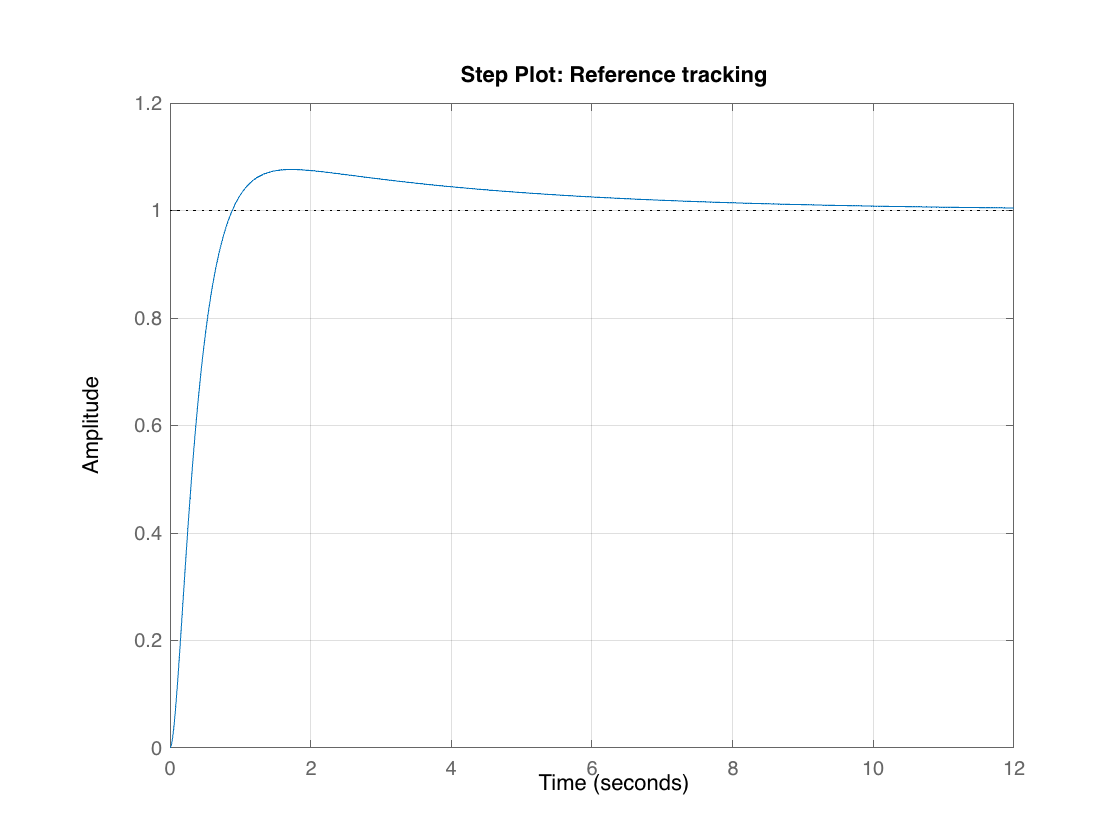

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.791734;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.729;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);

% PID tuning algorithm for linear plant model
[C,pidInfo] = pidtune(posTF,'PI',wc,opts);

% Clear Temporary Variables
clear wc PM opts

% Get desired loop response
Response = getPIDLoopResponse(C,posTF,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response))

         RiseTime: 0.5673
    TransientTime: 6.8173
     SettlingTime: 6.8173
      SettlingMin: 0.9053
      SettlingMax: 1.0763
        Overshoot: 7.6252
       Undershoot: 0
             Peak: 1.0763
         PeakTime: 1.7283




% Clear Temporary Variables
clear Response
KP = C.Kp, KI = C.Ki

KP = 69.8954

KI = 17.5457

## Discussion of Results 

I'm writing this on Monday, 2/28, at 9pm. I have spent hours upon hours of my own time figuring out how to correctly design and implement a controller, and I finally got it working at around 8 pm today. I have put a ridiculous amount of time into creating this matlab script and implementing it on the Arduino, and despite recieving incorrect advice from professors, I managed to design and implement a controller that works exactly as it's intended to. I may not have created a simulink file implementing my controller on the Arduino, but I didn't have any reason to. If I wasn't the only person working on this subsystem and wasn't taking five other classes, I would genuinely have loved to make a closed loop response experiment to show how great my controller is, but for now, I'm proud of what I've accomplished and thrilled that it's finally working.